# Step responses with MATLAB

Step responses are very common in real applications as these represent a simple change in some value which otherwise is assumed constant. This could be a target behaviour (e.g. pressure, temperature, speed, altitude) or a change in a disturbance (wind speed, road slope, external termperature, etc.) or indeed many other things.

For convenience MATLAB provides code that gives a **UNIT STEP RESPONSE**, that is, assume the change in the input is **ONE**. For linear systems simple scaling of the result can be used to determine the numerical values for different magnitudes of step. 

This file illustrates the core functionality of ***step.m*** and therefore how it can be used for system analysis and the production of neat figures for reports. This file focuses on transfer function models, but ***step.m*** can take other model formats (see *help step*). Users may find the file ***plotting_with_matlab.mlx*** useful to understand more on preparing plots for reports.

The ***step.m*** function in MATLAB assumes that the system is represented by a linear model (typically transfer function or state space). This file needs the control toolbox.

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

File written by J.A.Rossiter, University of Sheffield                    

## Table of contents

- Basic operation of step.m 

- Controlling the end time of the figure

- Collecting the numerical values of the step response

- Overlaying responses with step.m

- Overlaying responses in report writing

- Different input magnitudes

## 1. Basic operation of step.m 

The simplest use of ***step.m*** is to allow MATLAB to take all the decisions, such as, for how long is the step response wanted, how many points shall I calculate the response at and so forth; to do this simply provide  the transfer function (or model) as in line 2. This option produces a figure.  Change lines 1 and 4 below to explore different transfer functions.

G = tf([1 2],[1 5 8])   %%% Create  linear system

G =
 
      s + 2
  -------------
  s^2 + 5 s + 8
 
Continuous-time transfer function.



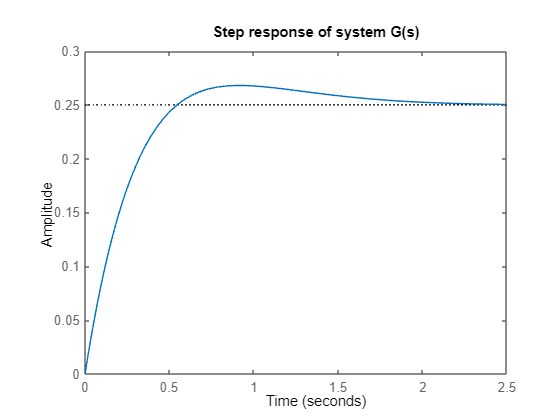

step(G)
title('Step response of system G(s)')

#### 2nd example

H = tf([1 2],[1 3 10 9])   %%% Create  linear system

H =
 
          s + 2
  ----------------------
  s^3 + 3 s^2 + 10 s + 9
 
Continuous-time transfer function.



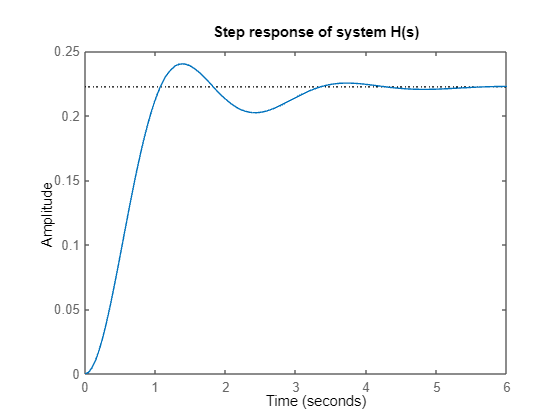

figure
step(H)
title('Step response of system H(s)')

## 2. Controlling the end time of the figure 

Should you want to insist on the time scale used for the step response, simply add a second input argument as a scalar which is the end time as seen in line 14 below (value defined in line 11).  Try changing the end times in lines 11 and 16 and observing the impact on the figures.

disp('BELOW is SECTION 2')

BELOW is SECTION 2


endtimeG = 1

endtimeG = 1

G = tf([1 2],[1 5 8])   %%% Create  linear system

G =
 
      s + 2
  -------------
  s^2 + 5 s + 8
 
Continuous-time transfer function.



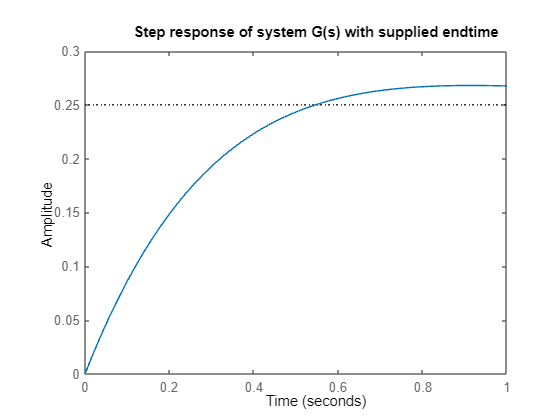

figure
step(G,endtimeG)
title('Step response of system G(s) with supplied endtime')

#### 2nd example

endtimeH = 3

endtimeH = 3

H = tf([1 2],[1 3 10 9])   %%% Create  linear system

H =
 
          s + 2
  ----------------------
  s^3 + 3 s^2 + 10 s + 9
 
Continuous-time transfer function.



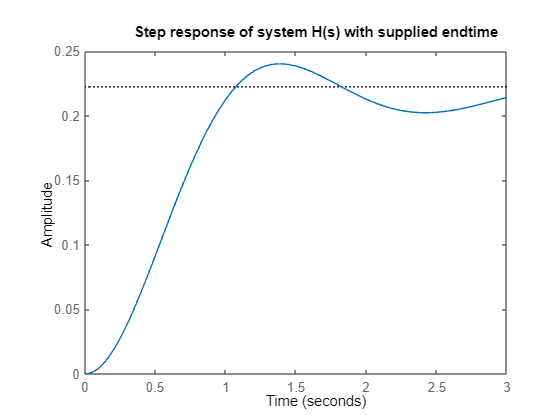

figure
step(H,endtimeH)
title('Step response of system H(s) with supplied endtime')

## 3. Collecting the numerical values of the step response

It may be that you want the numerical values of the step response. These are available by adding an output argument but, **NOTE**, if you request outputs, then ***step.m*** **will no longer generate a figure**! Actually this is often better in the long term as you can plot your own figure using the data provided and this gives you more control of what the figure looks like (line colours, width, styles and so forth).

You can just collect the output values, but in my view this makes no sense and you should always collect both the outputs and the corresponding times. An output value without a corresponding time may not be telling you much! The required command is in line 25 below.

disp('BELOW is SECTION 3')

BELOW is SECTION 3


endtimeG = 1.2;
G = tf([1 2],[1 5 8]);   %%% Create  linear system
[yvaluesg, ytimesg] = step(G,endtimeG)

yvaluesg =          0
    0.0118
    0.0232
    0.0341
    0.0447
    0.0548
    0.0646
    0.0741
    0.0832
    0.0919


ytimesg =          0
    0.0120
    0.0240
    0.0360
    0.0480
    0.0600
    0.0720
    0.0840
    0.0960
    0.1080


#### Note how MATLAB decides the number of values to give you based on the system dynamics and the endtime.

You can easily plot this data if required, for example:

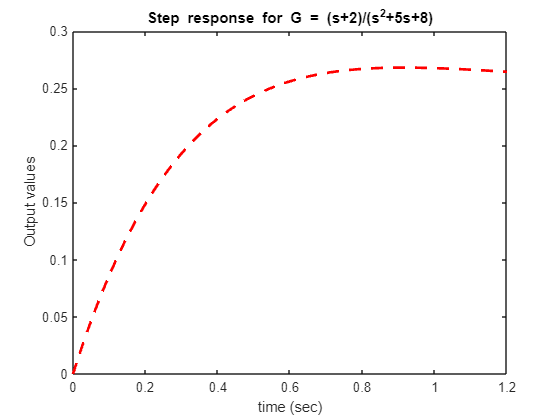

figure
plot(ytimesg, yvaluesg,'r--','linewidth',2)
ylabel('Output values')
xlabel('time (sec)')
title('Step response for G = (s+2)/(s^2+5s+8)')

#### 2nd example

endtimeH = 3;
H = tf([1 2],[1 3 10 9]);   %%% Create  linear system
[yvaluesh, ytimesh] = step(H,endtimeH)

yvaluesh =          0
    0.0004
    0.0018
    0.0039
    0.0069
    0.0106
    0.0150
    0.0200
    0.0257
    0.0319


ytimesh =          0
    0.0300
    0.0600
    0.0900
    0.1200
    0.1500
    0.1800
    0.2100
    0.2400
    0.2700


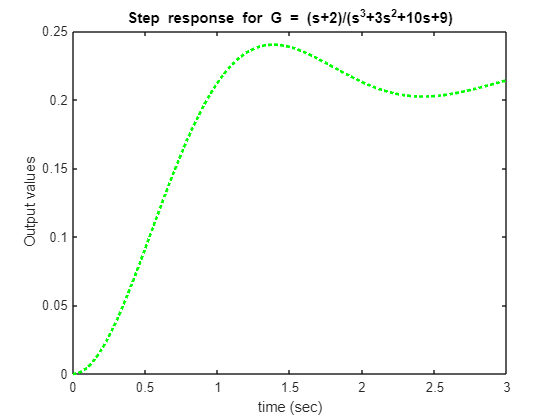

figure
plot(ytimesh, yvaluesh,'g:','linewidth',2)
ylabel('Output values')
xlabel('time (sec)')
title('Step response for G = (s+2)/(s^3+3s^2+10s+9)')

**REMARK: Find the numerical value at a specific time instant**

While there are numerous ways to do this, it is clear that the last value of the output corresponds to the endtime, hence one can find the output at the endtime using the simple statement:

y_at_endtimeG = yvaluesg(end)   %% last value from response of G(s)

y_at_endtimeG = 0.2643

y_at_endtimeH = yvaluesh(end)   %% last value from response of H(s)

y_at_endtimeH = 0.2141

## 4. Overlaying responses with step.m

You can overlay the step responses of multiple different systems. If you just want a figure, as mentioned in section 2, do not include any output arguments in the call statement. The last input argument will be interpreted as 'endtime' if it is a simple positive scalar.

**Figure with MATLAB determining the end time**

disp('BELOW is SECTION 4')

BELOW is SECTION 4


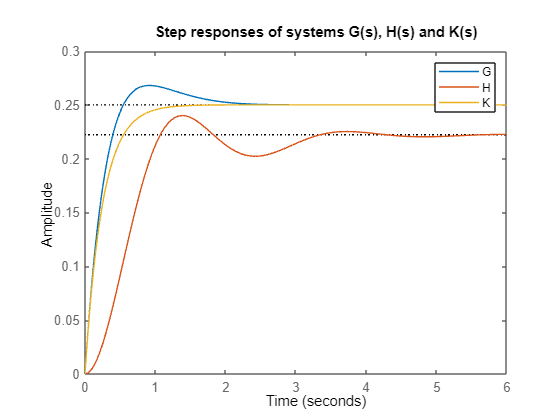

G = tf([1 2],[1 5 8]);   %%% Create  linear system
H = tf([1 2],[1 3 10 9]);   %%% Create  linear system
K = tf([1],[1 4]);   %%% Create  linear system
figure
step(G,H,K)       
legend('G','H','K')
title('Step responses of systems G(s), H(s) and K(s)')

**Figure with user selected end time**

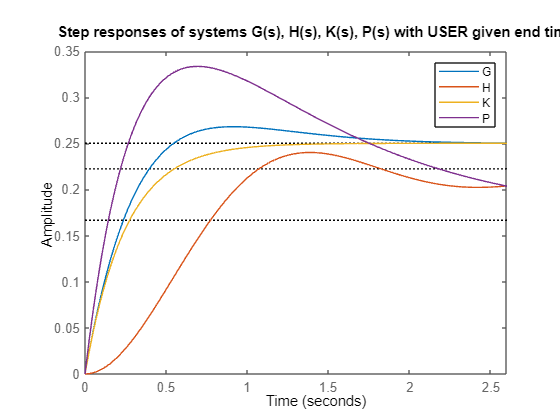

P = tf(0.5*[3 1],[1 4 3]);   %%% Create  linear system
endtimeP=2.6;
figure
step(G,H,K,P,endtimeP)       
legend('G','H','K','P')
title('Step responses of systems G(s), H(s), K(s), P(s) with USER given end time')

## **5. Overlaying responses in report writing**

If you want to control the figure more carefully, then it is better to collect all the data as in section 3 and generate the plot yourself. This allows you to control the colours, labels and line types more directly. You may also want to specify the time spacing of the values and this can be done by entering an equispaced vector in place of endtime.

The plots here looked disjointed because, **for illustration**, we only compute the outputs at 0.5 sec intervals (see *timespacing on line 57*).

disp('BELOW is SECTION 5')

BELOW is SECTION 5


timespacing = linspace(0,5,11)

timespacing =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


[yvaluesg] = step(G,timespacing)

yvaluesg =          0
    0.2434
    0.2675
    0.2585
    0.2524
    0.2504
    0.2500
    0.2500
    0.2500
    0.2500


[yvaluesh] = step(H,timespacing)

yvaluesh =          0
    0.0917
    0.2125
    0.2383
    0.2127
    0.2026
    0.2141
    0.2242
    0.2242
    0.2210


[yvaluesp] = step(P,timespacing)

yvaluesp =          0
    0.3212
    0.3174
    0.2708
    0.2327
    0.2073
    0.1915
    0.1817
    0.1758
    0.1722


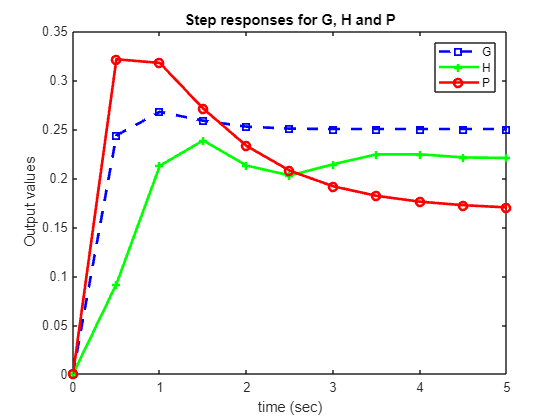

figure
aa=plot(timespacing,yvaluesg,'bs--',timespacing, yvaluesh,'g+-',timespacing,yvaluesp,'ro-');
set(aa,'linewidth',2)
legend('G','H','P')
ylabel('Output values')
xlabel('time (sec)')
title('Step responses for G, H and P')

## 6. Different input magnitudes

In practice the input will not be a unit step but some other value. This is easiest to manage by beginning from the technique showed in section 5 above, that is, first collect all the values and then create the plot yourself using the plot command.

If *yvalues* contains the step response with an input of '1', then for an input of magnitude 'A', simply multiply the *yvalues* by A. 

In code below 'A' is set in line 71 and you see this value is also used in the plot command of line 73.

disp('BELOW is SECTION 6')

BELOW is SECTION 6


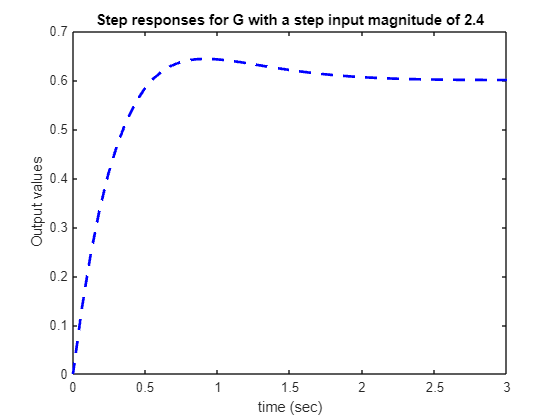

timespacing = linspace(0,3,50);
[yvaluesg] = step(G,timespacing);
inputmagnitude = 2.4;
figure
bb=plot(timespacing,yvaluesg*inputmagnitude,'b--');
set(bb,'linewidth',2)
ylabel('Output values')
xlabel('time (sec)')
title(['Step responses for G with a step input magnitude of ', num2str(inputmagnitude)])